# HSFP Probabilities Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 15/06/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

#### **Test Data: **ASSET Log Dif Returns & Smoothed Singal Data

"DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat"

"DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat"

*Note: SMTH-3M3Y denotes the half-lives used to smooth*

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path for HSFP Fns folder

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/HSFP/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/HSFP/', exportName);

## 2. Load Test Data

#### 2.1 ASSET Log Dif Returns

fileName = "DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat";
load(fileName)

#### 2.2 Scored Signal Data

% fileName = "DATA-PROCESSED-SIG-SMTH_NORM-M-TTABLE-20070531-20230228.mat";
% load(fileName)

fileName = "DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat";
load(fileName)

% Get the number of rows in the timetable object
numRows = height(SIG_SMOOTHED_TT);

% Remove the first 2 row to make signals same dates as assets
SIG_SMOOTHED_TT = SIG_SMOOTHED_TT(2:numRows, :);

## 3. Generate HSFP Time Conditioned Prs

Window_len = 60;
% Rolling window Prs
p_rw = rw_probs(SIG_SMOOTHED_TT,Window_len);
% Exp Decay Prs
tau = 3*12; %tau set here is based on slow half-life used for Exp Ddecay in signal processing
p_es = es_probs(SIG_SMOOTHED_TT, tau);

% p_es(p_es==0)=10^-250; %avoid log(0) in ens computation
% log_scale_p_es = log(p_es);

#### 3.1.1 Plot Time Conditioned 

subplot(2,1,1);
HSFP_RW_plot = bar(ASSETCL_log_diff.Time, p_rw);
set(gca, 'YScale', 'log')
ylabel("Probability");
xlabel("Time");
title(['Rolling Window Conditioned Probabilities ( Window Length = ' num2str(Window_len) ')']);

subplot(2,1,2)
HSFP_ES_plot = bar(ASSETCL_log_diff.Time, p_es);
set(gca, 'YScale', 'log')
ylabel("Probability");
xlabel("Time");
title(['Exponential Decayed Conditioned Probabilities ( \tau = ' num2str(tau) ')']);
HSFP_TIME_CON_plot = gcf;

**Export Rolling Window Pr plot**

exportName = 'HSFP_TIME_CON_plot.pdf';
exportgraphics(HSFP_TIME_CON_plot,fullfile(imageExportpath,exportName),'Resolution',300);

## 4. GENERAL INPUT SETUP: HSFP State-Conditioned Prs 

Use CPI as test 

alpha = 0.1; % Ann uses 0.1
gamma = 2;
h = 0.5;
Signal_series_CPI = SIG_SMOOTHED_TT.lagged_SACPIYOY_Index;
z_target_UQ = 1.9;
z_target = -0.9;
z_target_LQ = -1.4;

### 4.1 Using Single Var: Crisp Prs

[p_cr_UQ, z_ub_UQ, z_lb_UQ, z_max_UQ,z_min_UQ] = cr_probs(Signal_series_CPI, alpha, z_target_UQ);
[p_cr, z_ub, z_lb, z_max,z_min] = cr_probs(Signal_series_CPI, alpha, z_target);
[p_cr_LQ, z_ub_LQ, z_lb_LQ, z_max_LQ,z_min_LQ] = cr_probs(Signal_series_CPI, alpha, z_target_LQ);

 z_ub, z_lb

%%%%%%% UPPER QUANTILE TARGET CRISP PLOT %%%%%%%%
subplot(3,1,1);
plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
hold on;
yline(z_target_UQ, 'r--',LineWidth= 1);
yline(z_ub_UQ, 'b--',LineWidth= 1);
yline(z_max_UQ, 'black',LineWidth= 1);
yline(z_lb_UQ, 'b--',LineWidth= 1);
yline(z_min_UQ, 'black',LineWidth= 1);
hold off;
ylabel("Z-scores");
xlabel("Time");
legend('CPI', 'z* target','crisp upper band','Z upper quantile line','crisp lower band','Z lower quantile line', 'Location', 'northeastoutside');
title(['UPPER Quantile Target: CPI with z* = ' num2str(z_target_UQ) ', \alpha = ' num2str(alpha) ]);


%%%%%%% INRANGE TARGET CRISP PLOT %%%%%%%%
subplot(3,1,2);
plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
hold on;
yline(z_target, 'r--',LineWidth= 1);
yline(z_ub, 'b--',LineWidth= 1);
yline(z_max, 'black',LineWidth= 1);
yline(z_lb, 'b--',LineWidth= 1);
yline(z_min, 'black',LineWidth= 1);
hold off;
ylabel("Z-scores");
xlabel("Time");
legend('CPI', 'z* target','crisp upper band','Z upper quantile line','crisp lower band','Z lower quantile line', 'Location', 'northeastoutside');
title([' IN RANGE Target: CPI with z* = ' num2str(z_target) ', \alpha = ' num2str(alpha) ]);
%%%%%%% LOWER QUANTILE TARGET CRISP PLOT %%%%%%%%
subplot(3,1,3);
plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
hold on;
yline(z_target_LQ, 'r--',LineWidth= 1);
yline(z_ub_LQ, 'b--',LineWidth= 1);
yline(z_max_LQ, 'black',LineWidth= 1);
yline(z_lb_LQ, 'b--',LineWidth= 1);
yline(z_min_LQ, 'black',LineWidth= 1);
hold off;
ylabel("Z-scores");
xlabel("Time");
legend('CPI', 'z* target','crisp upper band','Z upper quantile line','crisp lower band','Z lower quantile line', 'Location', 'northeastoutside');
title(['LOWER Quantile Target: CPI with z* = ' num2str(z_target_LQ) ', \alpha = ' num2str(alpha) ]);


### 4.2  Using Single Var: Kernel Prs

knl_check_prs = kl_probs(Signal_series_CPI, h , gamma , z_target);
sum(knl_check_prs);

bar(knl_check_prs)

## 5. HSFP Time- & State-Conditioned Prs

### 5. 1 Entropy Pooling

Select a suitable prior. Here we use the exponential decay prior as this conditions by time before we condition by state using crisp condition.

**Check NB: tau_prior is set based on rebalancing frequency**

tau_prior = 3*12; % Ann did 5 yrs
EPool_prior = es_probs(SIG_SMOOTHED_TT, tau_prior);
% bar(EPool_prior)

% Use exponential smoothing as prior
post_pr_CPI = ep_probs(Signal_series_CPI, alpha, z_target, EPool_prior);

% HSFP_KERNEL_plot = bar(SIG_SMOOTHED_TT.Time, knl_check_prs);
% set(gca, 'YScale', 'log')
% % ylim([10^-4, 10^-1])
% ylabel("Probability");
% xlabel("Time");

%%%%%%%  SIGNAL PLOT %%%%%%%%
subplot(4,1,1);
plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
% set(gca, 'YScale', 'log')
hold on;
yline(z_target, 'r--','Label', 'z*');
yline(z_ub, 'b--');
yline(z_max, 'black');
yline(z_lb, 'b--');
yline(z_min, 'black');
hold off;
ylabel("Z-scores");
xlabel("Time");
title(['Standardised CPI with z* & U/L Bound ( z* = ' num2str(z_target) ', \alpha = ' num2str(alpha) ')']);


% close all (COMMENT OUT TO PLOT)
%%%%%%%  CRISP PLOT %%%%%%%%
subplot(4,1,2);
HSFP_CRISP_plot = bar(SIG_SMOOTHED_TT.Time, round(p_cr,2));
% set(gca, 'YScale', 'log')
%  ylim([10^-10, 1])
ylabel("Probability");
xlabel("Time");
title(['Crisp Conditioned Probabilities ( z* = ' num2str(z_target) ', \alpha = ' num2str(alpha) ')']);


%%%%%%%  KERNEL PLOT %%%%%%%%
subplot(4,1,3);
HSFP_KERNEL_plot = bar(SIG_SMOOTHED_TT.Time, knl_check_prs);
    % set(gca, 'YScale', 'log')
% ylim([10^-7, 1])
ylabel("Probability");
xlabel("Time");
title(['Kernel Conditioned Probabilities ( z* = ' num2str(z_target) ', h = ' num2str(h) ', \gamma = ' num2str(gamma) ')']);
% Save the combined plot as an image file

%%%%%%%  ENTROPY POOL PLOT %%%%%%%%
subplot(4,1,4);
HSFP_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, post_pr_CPI);
set(gca, 'YScale', 'log')
ylim([10^-10, 1])
ylabel("Probability");
xlabel("Time");
title(['Entropy Pooling Time & State Conditioned Probabilities (z* = ' num2str(z_target) ', \alpha = ' num2str(alpha) ')']);
% Save the combined plot as an image file
HSFP_STATE_COND_plot = gcf;

#### **########## CONTINUE HERE ###########**

#### **Export STATE CONDITIONED Plot**

exportName = 'HSFP_STATE_COND_plot.pdf';
exportgraphics(HSFP_STATE_COND_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

## 6. HSFP Time- & MULTIPLE State-Conditioned Prs

Will use CPI & DLI (Domestic Leading Indicator):

Signal_series_CPI already extracted.

Signal_series_DLI = SIG_SMOOTHED_TT.lagged_OEZAKLAP_Index;

z_CPI_target = Signal_series_CPI(end);
z_DLI_target = Signal_series_DLI(end);
% Entropy pooling using z_target at time T
post_pr_CPI_T = ep_probs(Signal_series_CPI, alpha, z_CPI_target, EPool_prior);
post_pr_DLI_T = ep_probs(Signal_series_DLI, alpha, z_DLI_target, EPool_prior);

sum(post_pr_DLI_T)

ans = 1.0000

### 6.1 Equally weighted prs

#### 6.1.1 Only using CPI and DLI:

num_singals = 2;
EW_prs_0 = ones(1, num_singals);
EW_prs = EW_prs_0/sum(EW_prs_0);

% Combine the 2:
EW_CPI_DLI_pr = EW_prs(1)*post_pr_CPI_T +EW_prs(2)*post_pr_DLI_T;

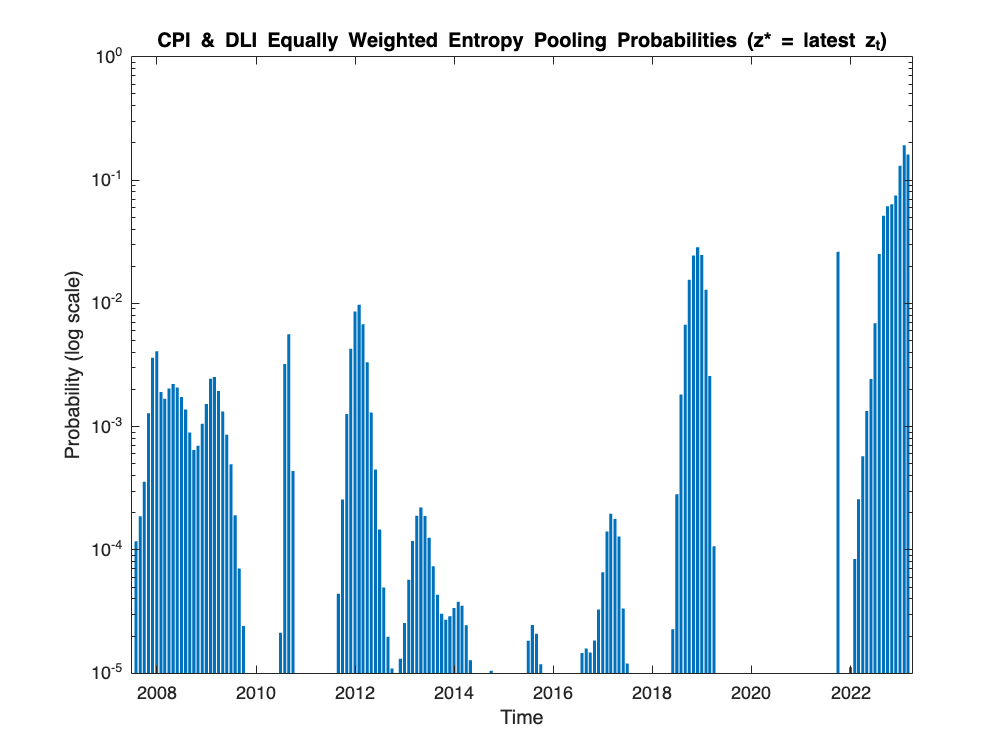

%%%%%%% GDP & DLI Combo ENTROPY POOL PLOT %%%%%%%%
HSFP_COMBO_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, EW_CPI_DLI_pr);
set(gca, 'YScale', 'log')
ylim([10^-5, 1])
ylabel("Probability");
xlabel("Time");
title('CPI & DLI Equally Weighted Entropy Pooling Probabilities (z* = latest z_t)');

#### 6.1.2 Ensemble EW of ALL singals

ew_ensemble(): Loop through all signals and calculate EPooled Prs for each then apply the EW Enseble approach

- Keep alpha and prior as used above.

ew_pr_ensemble = ew_ensemble(SIG_SMOOTHED_TT, alpha, EPool_prior, 'latest');
ens_EW_ensemble = ens(ew_pr_ensemble);

%%%%%%% ALL SIG EW Combo ENTROPY POOL PLOT %%%%%%%%
EW_all_plot = bar(SIG_SMOOTHED_TT.Time, ew_pr_ensemble);
% set(gca, 'YScale', 'log')
% ylim([10^-4, 1])
ylabel("Probability");
xlabel("Time");
title('EW All Signals Entropy Pooled Conditioned Ensemble Flexible Probabilities');

### 6.2 DCC weighted prs

#### 6.2.1 Checking Effective Number of Scenarios (ENS)

We first check **Effective Number of Scenarios** when:

- p = 1/t we have DCC minimized and ENS is maximal at J = t --> this exploits all information 

- p = 1 for a single scenario then DCC is maximized and ENS is minimal at J = 1 -->

% Probability for equally weighted scenarios
p_ew = ones(1, height(SIG_SMOOTHED_TT));
p_ew = p_ew/sum(p_ew);
% Probability for a single scenario case
p_single_sig = zeros(1,height(SIG_SMOOTHED_TT));
p_single_sig(1) = 1;

ens_ew = ens(p_ew); % result: 188, therefore maximum at J = T
ens_single_sig = ens(p_single_sig); % result: 1, therefore minimum at J = 1

Compare with a 'middle ground Pr'

ens_mid_test = ens(EW_CPI_DLI_pr); % result: 44.74, middle ground ENS.

#### 6.2.2 Applying to 2 singals: CPI & DLI

- ENS for each signal

- Bhattacharyya coefficient

- Hellinger Distance

- Diversity Index (DCC)

- Weight based on ENS & DCC

% % 1. effective number of scenarios
% ens_CPI = ens(post_pr_CPI_T);
% ens_DLI =ens(post_pr_DLI_T);
% 
% % 2. Bhattacharyya coefficient
% b_CPI_DLI_T = sum(sqrt(post_pr_CPI_T .* post_pr_DLI_T));
% 
% % 3. Hellinger distance
% h_CPI_DLI_T = sqrt(1 - b_CPI_DLI_T);
% 
% 
% 
% d_CPI = h_CPI_DLI_T;
% d_DLI = d_CPI;
% 
% w_numerator = [d_CPI*ens_CPI, d_DLI*ens_DLI];
% % w_q = w_numerator/ sum()
% % weight for each state variable using effective number of scenarios
% weight_state_var(roll_end,:) = [d1*ens_1, d2*ens_2];
% weight_state_var(roll_end,:) = weight_state_var(roll_end,:) ./ sum(weight_state_var(roll_end,:));
% 
% 
% % DCC or ensemble probability
% opt_prob = exp(weight_state_var(roll_end,1) * log(p_1) + weight_state_var(roll_end,2) * log(p_2));
% opt_prob = opt_prob ./ sum(opt_prob);
% p_entropy = opt_prob;

CPI_DLI_TT = timetable(SIG_SMOOTHED_TT.Time, ...
                          SIG_SMOOTHED_TT.lagged_OEZAKLAP_Index, ...
                          SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);

[cb_CPI_DLI_ensemble, CPI_DLI_wts, CPI_DLI_ens_vals] = cb_ensemble(CPI_DLI_TT, alpha, EPool_prior, 'latest');

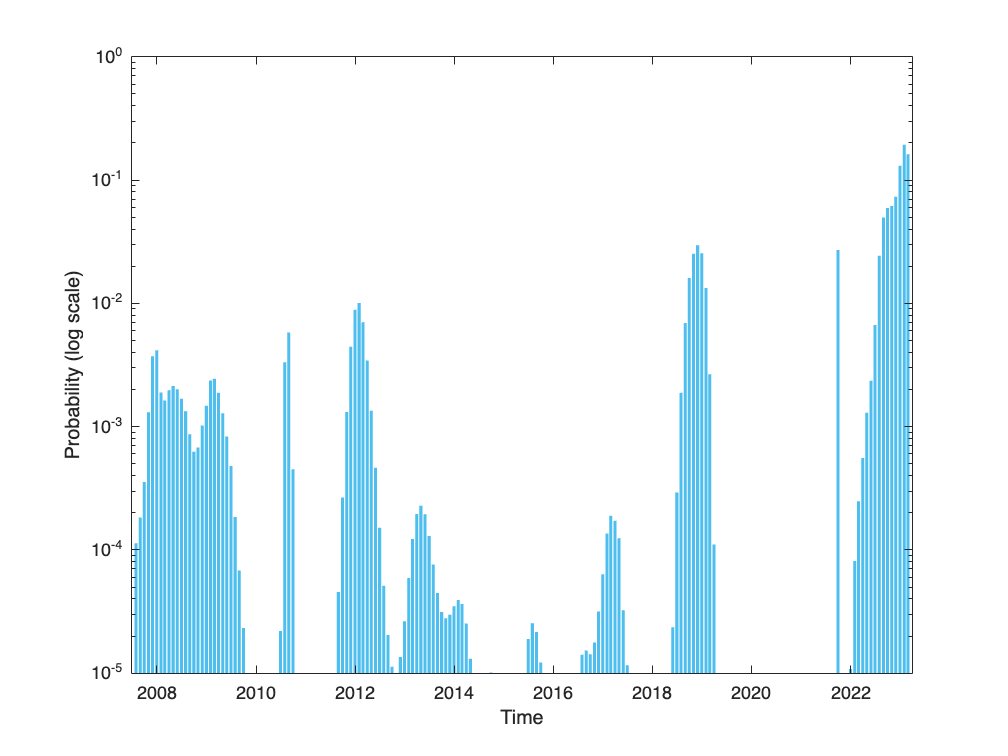

CB_CPI_DLI_plot = bar(SIG_SMOOTHED_TT.Time, cb_CPI_DLI_ensemble,'facecolor', [0.3010 0.7450 0.9330]);

set(gca, 'YScale', 'log')
ylim([10^-5, 1])
ylabel("Probability");
xlabel("Time");
hold off;
% Add legend
% legend('Conditioned Bayesian Ensemble', 'Equally Weighted Ensemble', 'Location','northwest');

Comparison plot

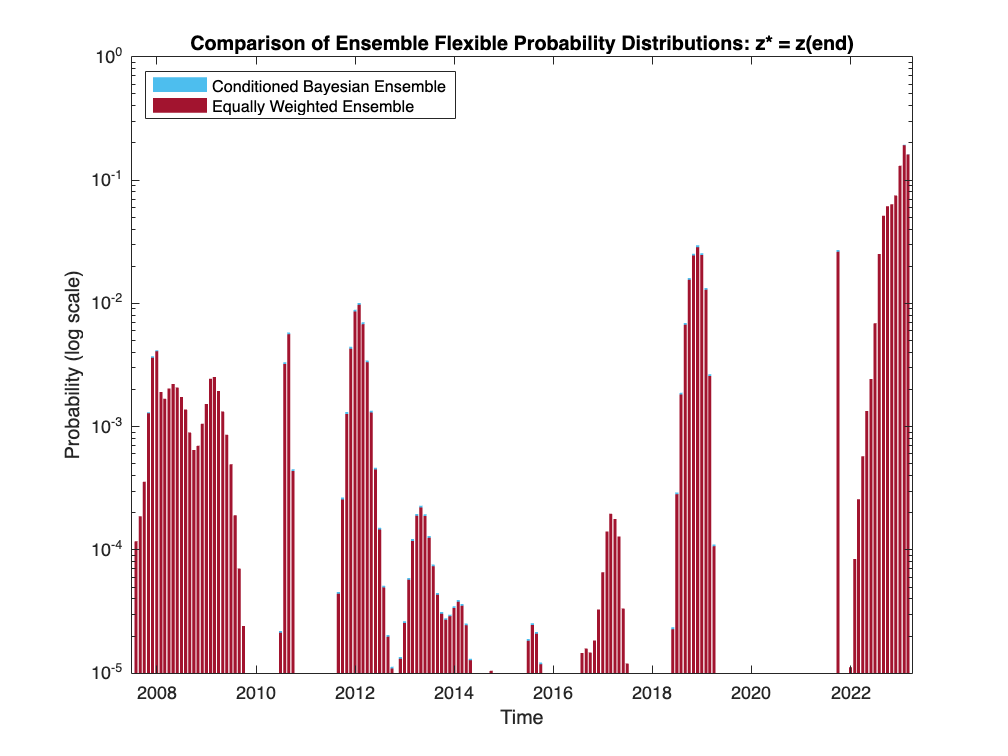

EW_CPI_DLI_plot = bar(SIG_SMOOTHED_TT.Time, EW_CPI_DLI_pr,'FaceColor',[0.6350 0.0780 0.1840]);
set(gca, 'YScale', 'log')
ylim([10^-5, 1])
ylabel("Probability");
xlabel("Time");
title('Comparison of Ensemble Flexible Probability Distributions: z* = z(end)');
hold on;

CB_CPI_DLI_plot = bar(SIG_SMOOTHED_TT.Time, cb_CPI_DLI_ensemble,'facecolor', [0.3010 0.7450 0.9330]);
set(gca, 'YScale', 'log')
ylim([10^-5, 1])

ylabel("Probability");
xlabel("Time");
hold off;
% Add legend
legend('Conditioned Bayesian Ensemble', 'Equally Weighted Ensemble', 'Location','northwest');

### 6.2.3 Ensemble DCC with all singals

[cb_pr_ensemble, wts, ens_vals] = cb_ensemble(SIG_SMOOTHED_TT, alpha, EPool_prior, 'latest');

% EW_plot = bar(SIG_SMOOTHED_TT.Time, ew_pr_ensemble,'FaceColor',[0.6350 0.0780 0.1840]);
% set(gca, 'YScale', 'log')
% ylim([10^-6, 1])
% ylabel("Probability (log scale)");
% xlabel("Time");
% title('Comparison of Ensemble Flexible Probability Distributions: z* = z(end)');
% hold on;
% 
% CB_plot = bar(SIG_SMOOTHED_TT.Time, cb_pr_ensemble,'facecolor', [0.3010 0.7450 0.9330]);
% set(gca, 'YScale', 'log')
% ylabel("Probability (log scale)");
% xlabel("Time");
% hold off;
% % Add legend
% legend('Conditioned Bayesian Ensemble', 'Equally Weighted Ensemble', 'Location','northwest');

EW_plot = bar(SIG_SMOOTHED_TT.Time, ew_pr_ensemble,'FaceColor',[0.6350 0.0780 0.1840]);
set(gca, 'YScale', 'log')
ylim([10^-7, 1])
ylabel("Probability");
xlabel("Time");
title('Comparison of Ensemble Flexible Probability Distributions: z* = avg(z)');
hold on;

CB_plot = bar(SIG_SMOOTHED_TT.Time, cb_pr_ensemble,'facecolor', [0.3010 0.7450 0.9330]);
set(gca, 'YScale', 'log')
ylabel("Probability");
xlabel("Time");
hold off;
% Add legend
legend('Conditioned Bayesian Ensemble', 'Equally Weighted Ensemble', 'Location','northwest');
HSFP_MULTISTATE_COMPARISON_plot = gcf;

exportName = 'HSFP_MULTISTATE_COMPARISON_plot.pdf';
exportgraphics(HSFP_MULTISTATE_COMPARISON_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

%%%%%%% CPI ENTROPY POOL PLOT %%%%%%%%
subplot(3,1,1);
HSFP_CPI_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, post_pr_CPI);
% hold on;
% plot(SIG_SMOOTHED_TT.Time, Signal_series_CPI, 'LineWidth', 1.5);
% % yline(z_CPI_target, 'r--','Label', 'z*');
% hold off;
ylabel("Probability");
xlabel("Time");
title(['CPI Entropy Pooling Conditioned Probabilities (z* = ' num2str(round(z_CPI_target,2)) ', \alpha = ' num2str(alpha) ')']);


%%%%%%% GDP ENTROPY POOL PLOT %%%%%%%%
subplot(3,1,2);
HSFP_GDP_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, post_pr_DLI_T);
ylabel("Probability");
xlabel("Time");
title(['GDP Entropy Pooling Conditioned Probabilities (z* = ' num2str(round(z_DLI_target,2)) ', \alpha = ' num2str(alpha) ')']);

%%%%%%% GDP & CPI Combo ENTROPY POOL PLOT %%%%%%%%
subplot(3,1,3);
HSFP_CPI_GDP_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, EW_CPI_DLI_pr);
ylabel("Probability");
xlabel("Time");
title(['GDP & CPI Entropy Pooling Conditioned Probabilities (z_{CPI}* =  ' num2str(round(z_CPI_target,2)) ', z_{GDP}* =  ' num2str(round(z_DLI_target,2)) ')']);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[cb_pr_ensemble, wts, ens_vals] = cb_test_ensemble(SIG_SMOOTHED_TT, alpha, EPool_prior, 'mean', 'log-linear');

sum(cb_pr_ensemble)

function [cb_ensemble, wts,ens_vals] = cb_test_ensemble(signal_TT, alpha, prior, target_method, wt_method)
% Calculates the Conditioned Bayesian Ensemble Posterior (CB_ensemble)
% flexible probabilities (also referred to as Degree of Conditioning &
% Correlation (DCC) Flex Prs) via entropy pooling given Q conditioning
% variables (signals).

%%% NOTE: z_target default for signal q is set as most recent obs of q.
% Code can later be updated to accommodate user defined targets per signal.
% Currently only 'mean' or 'latest' can be specified as method of selecting
% the target.

% INPUTS:
% singal_TT - time series of conditioning variables acting as state signals
% (Type: Timetable, [T x Q])

% alpha - range of probability for bandwidth
% (type: double)

% prior - desired prior probability distribution (usually exp smoothed Prs)
% (type: array double [T x 1])

% target_method - defines how target value should be selected
% Options: 'latest' - most recent observation of sig at time T (Default).
%          'mean' - average over time T for each sig.
% (Type: str|char)

% wt_method - way in which to weight the Q singals in the ensemble
% Options: 'simple' - simple weighted average across Q singals.
%          'log-linear' - log-linear weighted average across Q singals (Default).
% (Type: str|char)

%%
% check default method set for z_target
if nargin < 4|| isempty(target_method)
    target_method = 'latest';
end

% check default weighting method to log-linear
% if nargin < 5|| isempty(wt_method)
%     wt_method = 'log-linear';
% end

% check default weighting method to log-linear
if nargin < 5|| isempty(wt_method)
    wt_method = 'simple';
end

Q = width(signal_TT);

Post_pr_storage = zeros(size(signal_TT));
ens_vals = zeros(1, Q);

% Obtain the posterior Pr & ENS per Signal
for sig = 1:width(signal_TT)
    signal_series = signal_TT{:,sig};
    if strcmp(target_method, 'mean')
        z_target = mean(signal_series);
    elseif strcmp(target_method, 'latest')
        z_target = signal_series(end);
    end
    %% 1. Get posterior via Entropy Pooling
    Post_pr_storage(:,sig) = ep_probs(signal_series, alpha, z_target, prior);
    %% 2. ENS
    ens_vals(sig) = ens(Post_pr_storage(:,sig)');
end

%% 3. Bhattacharyya coefficient
B_Coeff = zeros(Q, Q);

% Calculate coefficient pairwise across Posterior Prs
for col1 = 1:Q
    for col2 = col1+1:Q
        % Select the columns for pairwise comparison
        column1 = Post_pr_storage(:, col1);
        column2 = Post_pr_storage(:, col2);

        % Calculate the Bhattacharyya coefficient
        bc = sum(sqrt(column1 .* column2));

        % Store the coefficient in the symmetric matrix
        B_Coeff(col1, col2) = bc;
        B_Coeff(col2, col1) = bc;
    end
end

%% 4. Hellinger distance

% Initialize an array to store the Hellinger distances
hellinger_dists = zeros(1, Q);

% Calculate Hellinger distance for each pairwise Bhattacharyya coefficient
for col1 = 1:Q
    for col2 = col1+1:Q
        % Select the columns for pairwise comparison
        bCoeff = B_Coeff(col1, col2);

        % Calculate the Hellinger distance using the formula: Hellinger_distance = sqrt(1 - B)
        hellinger_dists(col1, col2) = sqrt(1 - bCoeff);
        hellinger_dists(col2, col1) = sqrt(1 - bCoeff);
    end
end

%% 5. Diversity Indicators
d_indicators = zeros(1, Q);
for sig = 1:Q
    d_indicators(sig) = (1/(Q-1)).*sum(hellinger_dists(:,sig),1);
end

%% 6. Calculating Weights
weighted_pr_storage = zeros(size(signal_TT));
products = ens_vals.*d_indicators;
wts = products/sum(products);

%% 7. Weighting all Q probabilites together
% 7.1 Simple weighted average
if strcmp(wt_method, 'simple')
    for sig = 1:Q
        weighted_pr_storage(:,sig) = wts(sig)*Post_pr_storage(:,sig);
    end
    cb_ensemble = sum(weighted_pr_storage, 2)';
    % 7.2 Log-linear weighted average
elseif strcmp(wt_method, 'log-linear')
    for sig = 1:Q
        weighted_pr_storage(:,sig) = wts(sig)*log(Post_pr_storage(:,sig));
%         weighted_pr_storage(:,sig) = expweighted_pr_storage(:,sig));
    end

    cb_ensemble = sum(weighted_pr_storage, 2)';
    cb_ensemble = exp(cb_ensemble);
    cb_ensemble = cb_ensemble./sum(cb_ensemble);
end

end